# Trajectory Generation

## Load the map

load trajectories/complexmap2.mat;
Resolution=0.1; % meters
map = binaryOccupancyMap(complexMap,Resolution);
uavRadius = .5;

% inflate map
inflate(map,uavRadius);
%save('trajectories/map', 'map');

## Create waypoints

start = [50 25];
waypoint1 = [260 40];
waypoint2 = [270 90];
%waypoint1 = [260 80];
%waypoint1 = [440 190];
%waypoint3 = [330 230];
%waypoint4 = [80 375];
waypoint5 = [480 100];
%waypoint1 = [45 165];
waypoint3 = [210 90];
waypoint1 = [100 230];
waypoint2 = [250 181];
waypoint6 = [310 60];
waypoint7 = [180 240];
% this is where preference happens
% changing priority increases diversity
waypoints = [waypoint1; waypoint2; waypoint3]%; waypoint4]%; waypoint5; waypoint6]%; waypoint7]%; waypoint8];% waypoint6];% waypoint2; waypoint3; waypoint4; waypoint5; waypoint6];

waypoints =    100   230
   250   181
   210    90


## Visualize map and waypoints

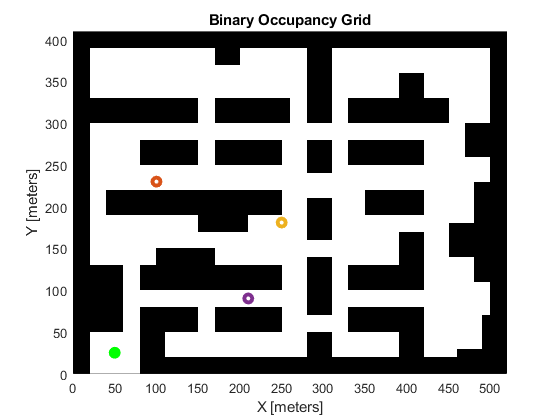

f1 = figure(1); clf;
hold on;
show(map);
plot(start(1), start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
for i = 1:length(waypoints(:,1))
   plot(waypoints(i,1), waypoints(i,2), 'o', 'LineWidth', 3); 
end
hold off;

## Build PRM

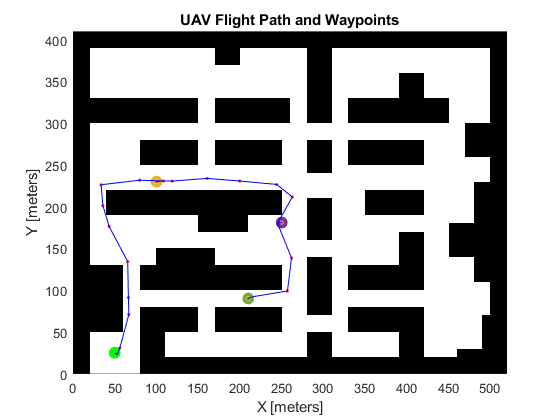

prm = mobileRobotPRM;
prm.Map = map;

prm.NumNodes = 1000;
prm.ConnectionDistance = 50;

path = findpath(prm, start, waypoint1);
for i = 2:length(waypoints(:,1))
   p = findpath(prm, waypoints(i-1,:), waypoints(i,:));
   path = [path; p];
end
f2 = figure(2); clf;
hold on;
show(map);
plot(path(:,1), path(:,2), 'r.', 'MarkerSize', 5)
plot(start(1), start(2), 'go', 'MarkerFaceColor', 'green', 'linewidth', 3);
for i = 1:length(waypoints(:,1))
   plot(waypoints(i,1), waypoints(i,2), 'o', 'LineWidth', 3); 
end
for i = 2:length(path-1)
    plot([path(i-1,1) path(i, 1)], [path(i-1,2) path(i, 2)], 'b');
end
hold off;
title("UAV Flight Path and Waypoints")

## Calculate flight parameters

desiredVelocity=1.3; % m/s
path_distance = calculatedistance(path); % total distance to be covered
time_interval = calculatetime(path_distance,desiredVelocity); 
stoptimetotal = time_interval(2)+0.25*time_interval(2); % time to complete the mission
% generate smooth time stamped trajectory
sampletimetraj=1; % 0.5 seconds by default
tSamples = sampletimetraj:sampletimetraj:time_interval(2);
[q,qd,qdd,pp] = bsplinepolytraj(path',time_interval,tSamples);
x_ref_points = [tSamples',q(1,:)'];
y_ref_points = [tSamples',q(2,:)'];


load_db_params;
conn = database(datasource_name, user_name, password);
clear('database_name', 'datasource_name', 'host_name', 'user_name', 'password');

x_points = "{49.47, 49.19, 49.13, 49.27, 49.61, 50.12, 50.78, 51.57, 52.48, 53.49, 54.58, 55.73, 56.93, 58.15, 59.39, 60.61, 61.80, 62.95, 64.04, 65.04, 65.96, 66.79, 67.55, 68.23, 68.85, 69.39, 69.88, 70.30, 70.67, 70.99, 71.27, 71.50, 71.69, 71.84, 71.97, 72.07, 72.14, 72.20, 72.24, 72.26, 72.28, 72.29, 72.28, 72.27, 72.24, 72.21, 72.17, 72.12, 72.07, 72.01, 71.95, 71.88, 71.81, 71.74, 71.66, 71.59, 71.51, 71.43, 71.35, 71.28, 71.20, 71.13, 71.05, 70.98, 70.91, 70.84, 70.78, 70.71, 70.65, 70.59, 70.53, 70.48, 70.42, 70.38, 70.33, 70.29, 70.25, 70.21, 70.18, 70.15, 70.13, 70.11, 70.09, 70.08, 70.07, 70.06, 70.06, 70.06, 70.06, 70.07, 70.08, 70.10, 70.12, 70.14, 70.17, 70.20, 70.24, 70.27, 70.32, 70.38, 70.46, 70.56, 70.69, 70.84, 71.03, 71.26, 71.53, 71.85, 72.22, 72.65, 73.14, 73.69, 74.31, 75.00, 75.77, 76.63, 77.57, 78.59, 79.68, 80.85, 82.07, 83.35, 84.68, 86.06, 87.46, 88.90, 90.35, 91.83, 93.31, 94.79, 96.27, 97.73, 99.18, 100.60, 101.99, 103.34, 104.65, 105.93, 107.17, 108.39, 

## Write trajectory data to db

x_points = convert_for_insert(round(x_ref_points(:,2), 2))

x_points = "{50.39, 50.77, 51.14, 51.49, 51.84, 52.18, 52.51, 52.83, 53.15, 53.47, 53.79, 54.10, 54.42, 54.74, 55.07, 55.40, 55.73, 56.08, 56.43, 56.80, 57.18, 57.57, 57.97, 58.38, 58.80, 59.22, 59.65, 60.08, 60.50, 60.93, 61.35, 61.76, 62.17, 62.57, 62.95, 63.32, 63.68, 64.02, 64.33, 64.63, 64.90, 65.15, 65.37, 65.57, 65.74, 65.89, 66.02, 66.14, 66.23, 66.30, 66.36, 66.41, 66.44, 66.46, 66.47, 66.47, 66.46, 66.45, 66.42, 66.40, 66.37, 66.33, 66.30, 66.26, 66.22, 66.17, 66.12, 66.05, 65.96, 65.86, 65.74, 65.60, 65.44, 65.24, 65.02, 64.77, 64.49, 64.17, 63.81, 63.42, 62.98, 62.49, 61.96, 61.38, 60.75, 60.08, 59.37, 58.63, 57.86, 57.07, 56.25, 55.42, 54.57, 53.72, 52.86, 51.99, 51.14, 50.28, 49.44, 48.62, 47.81, 47.03, 46.27, 45.55, 44.86, 44.20, 43.58, 42.99, 42.42, 41.89, 41.38, 40.90, 40.45, 40.02, 39.61, 39.22, 38.86, 38.52, 38.20, 37.89, 37.60, 37.33, 37.07, 36.83, 36.60, 36.38, 36.19, 36.02, 35.87, 35.76, 35.69, 35.67, 35.69, 35.76, 35.90, 36.09, 36.36, 36.69, 37.10, 37.60, 38.18, 

%write_trajectory_data;

trajectory_tb = 1×6 table
    path_distance    path_time           x_waypoints                   y_waypoints                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        

qer = "insert into trajectory_tb (path_distance, path_time, x_waypoints, y_waypoints, x_ref_points, y_ref_points) values (647.40, 8.30, '{100.00, 250.00, 210.00}', '{230.00, 181.00, 90.00}', '{50.39, 50.77, 51.14, 51.49, 51.84, 52.18, 52.51, 52.83, 53.15, 53.47, 53.79, 54.10, 54.42, 54.74, 55.07, 55.40, 55.73, 56.08, 56.43, 56.80, 57.18, 57.57, 57.97, 58.38, 58.80, 59.22, 59.65, 60.08, 60.50, 60.93, 61.35, 61.76, 62.17, 62.57, 62.95, 63.32, 63.68, 64.02, 64.33, 64.63, 64.90, 65.15, 65.37, 65.57, 65.74, 65.89, 66.02, 66.14, 66.23, 66.30, 66.36, 66.41, 66.44, 66.46, 66.47, 66.47, 66.46, 66.45, 66.42, 66.40, 66.37, 66.33, 66.30, 66.26, 66.22, 66.17, 66.12, 66.05, 65.96, 65.86, 65.74, 65.60, 65.44, 65.24, 65.02, 64.77, 64.49, 64.17, 63.81, 63.42, 62.98, 62.49, 61.96, 61.38, 60.75, 60.08, 59.37, 58.63, 57.86, 57.07, 56.25, 55.42, 54.57, 53.72, 52.86, 51.99, 51.14, 50.28, 49.44, 48.62, 47.81, 47.03, 46.27, 45.55, 44.86, 44.20, 43.58, 42.99, 42.42, 41.89, 41.38, 40.90, 40.45, 40.02, 39.61, 39

## Load trajectory data

- Trajectories were loaded to a csv file from the database first

%trajectory_tb = sqlread(conn, 'trajectory_tb');
trajectory_tb = readtable('trajectories/trajectories.csv');
max_flight_time = 22.0;

trajectory_tb = trajectory_tb(trajectory_tb.path_time < max_flight_time, :);
trajectory_tb = sortrows(trajectory_tb, "path_time", 'descend');
% randomly select one of the top 3 missions, or the first
if height(trajectory_tb) > 3
    idx = randi(3,1);
else
    idx = 1;
end
trajectory = table2struct(trajectory_tb(4,:));
trajectory.x_waypoints = str2double(regexp(trajectory.x_waypoints,'[+-]?\d+\.?\d*','match'));
trajectory.y_waypoints = str2double(regexp(trajectory.y_waypoints,'[+-]?\d+\.?\d*','match'));
trajectory.x_ref_points = str2double(regexp(trajectory.x_ref_points,'[+-]?\d+\.?\d*','match'))';
trajectory.y_ref_points = str2double(regexp(trajectory.y_ref_points,'[+-]?\d+\.?\d*','match'))';
times = [1:1:length(trajectory.x_ref_points)]';
trajectory.x_ref_points = [times trajectory.x_ref_points];
trajectory.y_ref_points = [times trajectory.y_ref_points];
clear('trajectory_tb', 'times', 'idx');

max_flight_time = 18;
trajectory = get_trajectory('trajectories.csv', max_flight_time)

trajectory = struct with fields:
             Var1: 2
               id: 3
    path_distance: 1.3906e+03
        path_time: 17.8300
      risk_factor: 0.0100
     x_ref_points: [1069×2 double]
     y_ref_points: [1069×2 double]
      sample_time: 1
           reward: 1
        waypoints: [4×2 double]
